# Divergent Neural Processing of Self-Referential Stimuli in Orbitofrontal and Ventromedial Cortex Populations 

% -*- UFT -*-
% Author: behira
% behzadiravani@gmail.com
% loading the data
clc
clear 
data = readtable('data\stimlock.tsv', FileType='text'); % reading the tabular data

## Subject and Experimental Condition

% create report object 
report = stat_report(data, 'data\BHV.json', 'data\FrontalEcogvsSeeg.json'); % stat_report instance
% print some info
Uniq_id = report.report("num_indiv");

The total number of pt is: 22

 

report.report("number_total_elec"); % statistical summary of the number of electrodes

The total number of elec is: 253, in total patients 22
 mean (std) # elec: 11.50(10.60), range =  [1,38]

 

## Behavioral Data

Finding out how many trials per conditions have been performed on average. 

report.report("number_trials"); % statistical summary of the number of trials per condition 

EP # trails: mean (std): 24 (1.2)
SJ # trails: mean (std): 24 (1.9)
MTH # trails: mean (std): 39 (1.7)


report.report("number_true_false") % statistical summary of the number of trials responded with true and false

EP true # trails replied with true: mean (std): 9 (4), range = [4,22]
EP false # trails replied with true: mean (std): 15 (4), range = [4,21]
SJ true # trails replied with true: mean (std): 16 (3), range = [8,23]
SJ false # trails replied with true: mean (std): 8 (3), range = [3,14]
MTH true # trails replied with true: mean (std): 21 (4), range = [15,31]
MTH false # trails replied with true: mean (std): 16 (3), range = [9,20]


ans = struct with fields:
     true: {[9 4 4 22]  [16 3 8 23]  [21 4 15 31]}
    false: {[15 4 4 21]  [8 3 3 14]  [16 3 9 20]}


report.report("reaction_time") % statistical summary of the RT responded with true and false

EP true RT replied with true: mean (std): 3.67 (1.40), range = [1.35,6.48]
EP false RT replied with true: mean (std): 3.62 (1.40), range = [1.38,6.45]
SJ true RT replied with true: mean (std): 3.06 (1.33), range = [0.96,5.49]
SJ false RT replied with true: mean (std): 3.56 (1.27), range = [1.16,5.86]
MTH true RT replied with true: mean (std): 4.65 (1.84), range = [1.22,8.32]
MTH false RT replied with true: mean (std): 5.37 (2.04), range = [1.34,9.47]


ans = struct with fields:
     true: {[3.6700 1.4000 1.3500 6.4800]  [3.0600 1.3300 0.9600 5.4900]  [4.6500 1.8400 1.2200 8.3200]}
    false: {[3.6200 1.4000 1.3800 6.4500]  [3.5600 1.2700 1.1600 5.8600]  [5.3700 2.0400 1.3400 9.4700]}


report.report("veridicality") % statistical summary of the response veridicality.

EP true veridicality replied with true: mean (std): 0.47 (0.15), range = [0.24,0.82]
EP false veridicality replied with true: mean (std): 0.70 (0.21), range = [0.11,0.96]
MTH true veridicality replied with true: mean (std): 0.87 (0.11), range = [0.60,1.00]
MTH false veridicality replied with true: mean (std): 0.79 (0.20), range = [0.29,1.00]


ans = struct with fields:
     true: {[0.4700 0.1500 0.2400 0.8200]  [0.8700 0.1100 0.6000 1]}
    false: {[0.7000 0.2100 0.1100 0.9600]  [0.7900 0.2000 0.2900 1]}


## Self-Referential Neuronal Population Activity in the OFC and vmPFC 

report.report("ECoGSEEG") % statisitcal summary of the number of ECoG and SEEG electrodes as well as OFC and vmPFC(MPFC)

S01 -- electype: ECOG
S02 -- electype: ECOG
S03 -- electype: ECOG
S04 -- electype: ECOG
S05 -- electype: ECOG
S06 -- electype: ECOG
S07 -- electype: ECOG
S08 -- electype: ECOG
S09 -- electype: ECOG
S10 -- electype: ECOG
S11 -- electype: ECOG
S12 -- electype: ECOG
S13 -- electype: ECOG
S14 -- electype: ECOG
S15 -- electype: ECOG
S16 -- electype: ECOG
S17 -- electype: SEEG
S18 -- electype: ECOG
S19 -- electype: SEEG
S20 -- electype: ECOG
S21 -- electype: SEEG
S22 -- electype: SEEG
ECOG = 13 +/- 11, [2, 38]
OFC = 0.76 +/- 0.33
MPFC = 0.24 +/- 0.33
SEEG = 6 +/- 6, [1, 13]
OFC = 0.50 +/- 0.58
MPFC = 0.50 +/- 0.58


Assessing the spatial distribution of self-referntial- and math-activated electrodes on the cortex. The significance has been determined by 5000 permutations Monte Carlo test and stored in Pval_LOC in the data table. 

Starting parallel pool (parpool) using the 'local' profile ...


Connected to the parallel pool (number of workers: 8).
observation 1 of 107
observation 2 of 107
observation 3 of 107
observation 4 of 107
observation 5 of 107
observation 6 of 107
observation 7 of 107
observation 8 of 107
observation 14 of 107
observation 13 of 107
observation 12 of 107
observation 11 of 107
observation 10 of 107
observation 9 of 107
observation 59 of 107
observation 58 of 107
observation 57 of 107
observation 84 of 107
observation 83 of 107
observation 98 of 107
observation 106 of 107
observation 20 of 107
observation 19 of 107
observation 18 of 107
observation 17 of 107
observation 16 of 107
observation 15 of 107
observation 80 of 107
observation 79 of 107
observation 78 of 107
observation 94 of 107
observation 93 of 107
observation 103 of 107
observation 26 of 107
observation 25 of 107
observation 24 of 107
observation 23 of 107
observation 22 of 107
observation 21 of 107
observation 74 of 107
observation 73 of 107
observation 72 of 107
observation 88 of 107
observ

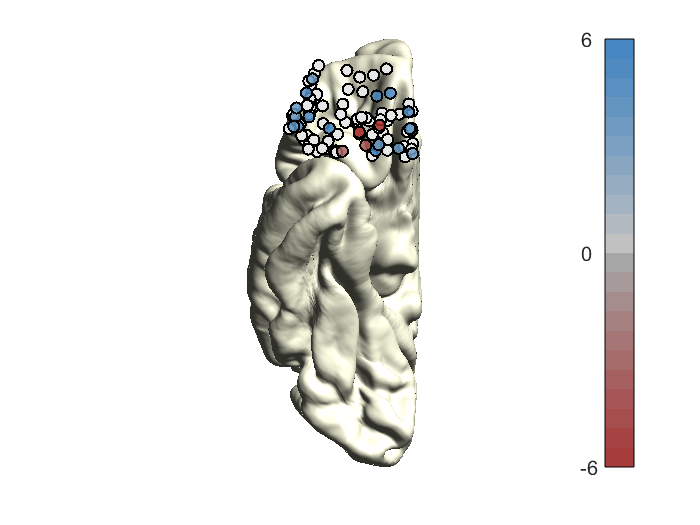

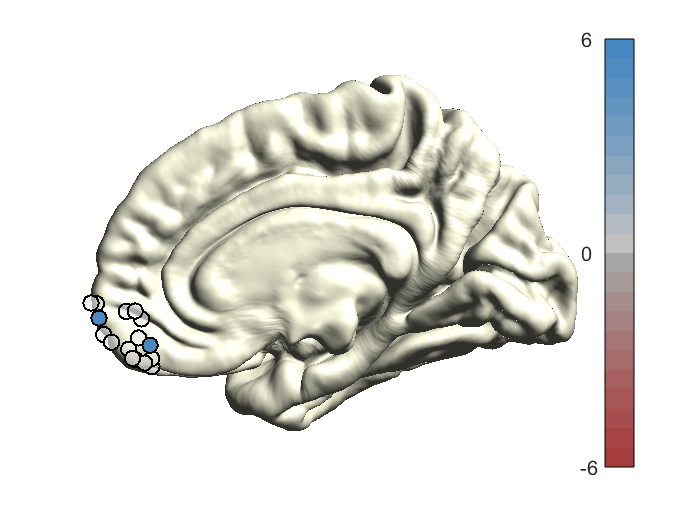

observation 1 of 146
observation 2 of 146
observation 3 of 146
observation 4 of 146
observation 6 of 146
observation 7 of 146
observation 8 of 146
observation 17 of 146
observation 16 of 146
observation 15 of 146
observation 14 of 146
observation 13 of 146
observation 12 of 146
observation 11 of 146
observation 10 of 146
observation 9 of 146
observation 26 of 146
observation 25 of 146
observation 24 of 146
observation 23 of 146
observation 22 of 146
observation 21 of 146
observation 20 of 146
observation 19 of 146
observation 18 of 146
observation 35 of 146
observation 34 of 146
observation 33 of 146
observation 32 of 146
observation 31 of 146
observation 30 of 146
observation 29 of 146
observation 28 of 146
observation 27 of 146
observation 44 of 146
observation 43 of 146
observation 42 of 146
observation 41 of 146
observation 40 of 146
observation 39 of 146
observation 38 of 146
observation 37 of 146
observation 36 of 146
observation 5 of 146
observation 53 of 146
observation 52 of 1

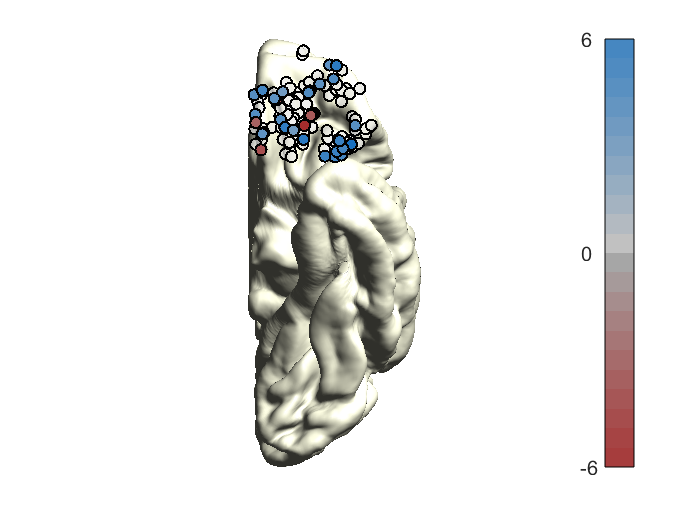

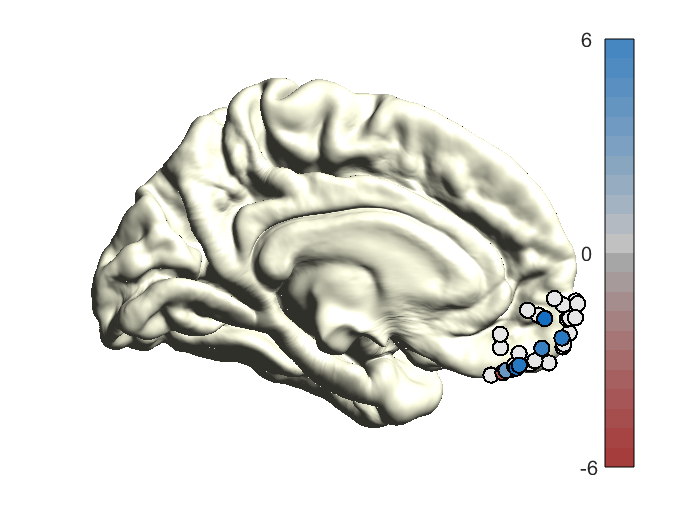

R = resultiEEG(data, 'data\BHV.json', 'data\FrontalEcogvsSeeg.json'); % cerate an instance of resultiEEG object 
% define the colors for electrode activity in hex
col = ["#0065C1",... blue for self-referential 
        "#A63838" ]; % red for math 
R.LocalizeSelfMath(col);

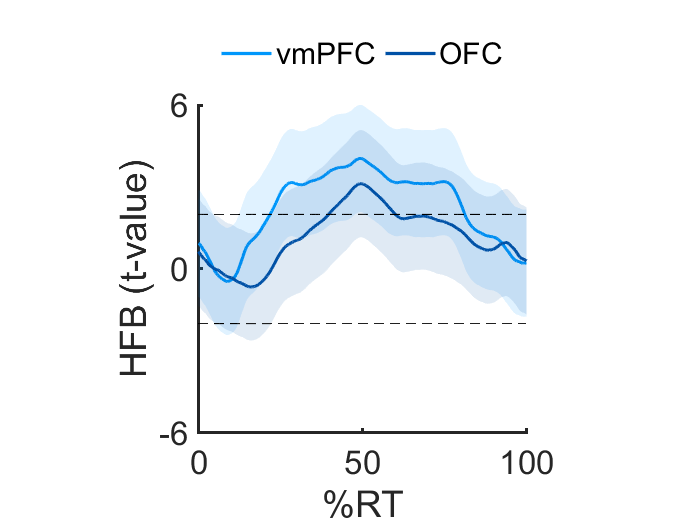

{
  "Anatomy": [
    "MPFC",
    "OFC"
  ],
  "time": [
    22,
    40
  ],
  "tvalue": [
    2.0582317462587456,
    2.0515793356025762
  ],
  "dof": [
    38,
    207
  ],
  "pvalue": [
    0.046473355236149594,
    0.041469574463316672
  ],
  "CI": [
    [
      -0.052999750339447149,
      0.067882795654500033
    ],
    [
      -0.11636782753021721,
      0.131640396275843
    ]
  ]
}


% read the time warped HFB envelope
HFB_tw.data  = R.getTimeWarppedHFB('data\Stimlock-TimeWarped_ieeg.dat');
% read labels 
HFB_tw.label = readtable('data\Stimlock-TimeWarped.tsv', FileType = 'text');
% trials were warped to 0:100% of RT 
HFB_tw.time  = (0:size(HFB_tw.data,2)-1)./512 - .5; % pre = 500ms, fsamp = 512
% define colors 
col = ["#0097FB", "#0051A6"]; % light and dark blue 
R.plot_HFB(HFB_tw, .1, col) % smoothing .1s 

Testing if in the same brain a pattern similar to group level can be found. Therefore, we need to first find individuals with electrode implanted both in OFC and vmPFC. 

[SE, SJ] = R.find_sameBrain(HFB_tw.label, HFB_tw.data, HFB_tw.time); % finds data from same brains
t2p = time2peak(SE, SJ) % create time2peak object 

t2p =   time2peak with properties:

                       SE: [14×18 table]
                       SJ: [14×18 table]
    HFB_response_latencey: [1×1 struct]


Peaks were identified using matlab findpeaks, the first peak identified as the peak that had an amplitude larger than 75th percentile and the latency larger 10% of RT.

t2p.HFB_response_latencey % calculate the response latency for HFB in the same brains

ans = struct with fields:
     OFC: [47.2058 21.5072 16.2574 66.2574 39.4157 25.1482 24.0051]
    MPFC: [46.7401 20.2794 14.1829 46.2320 28.4928 30.6097 49.6190]


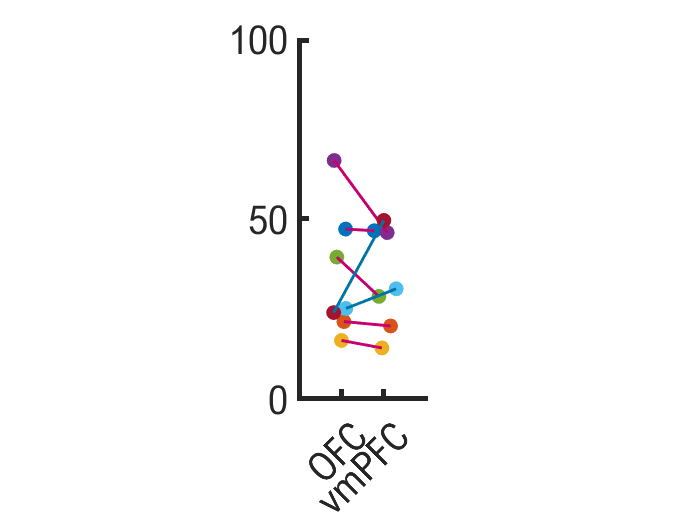

% ploting the results (fig1c)
figure
t2p.plot()

Now we assess how many percentages of the electrodes were activated during self-referential vs. math.

out = report.report("active_total"); % how many electrodes were activated per each condition: self > math -> self, self < math -> math, self = math -> not selective  
fprintf('total of %1.0f(%1.0f)%% self-activated\n', mean(cellfun(@(x) x.self, out))*1e2, std(cellfun(@(x) x.self, out))*1e2)

total of 13(15)% self-activated


fprintf('total of %1.0f(%1.0f)%% math\n', mean(cellfun(@(x) x.math, out))*1e2, std(cellfun(@(x) x.math, out))*1e2)

total of 4(5)% math


Performing a paired t-test to assess if the difference between the percentage of self- vs. math-activated electrodes are statistically meaningful. 

% calculate two-ways, paired t-test to compare the percentages of self- vs. math-activated electrodes  
[~, p, CI, stats ] = ttest(cellfun(@(x) x.self, out), cellfun(@(x) x.math, out));
fprintf('self > math: t(%d) = %1.2f, p < %1.2f, CI = [%1.2f, %1.2f]', stats.df, stats.tstat, p, CI)

self > math: t(21) = 2.80, p < 0.01, CI = [0.02, 0.16]

We further assess if the self-episodic and self-judgment electrodes within the self-referentially activated populations overlaps. 

out = report.report("percentage");
fprintf('total of %1.0f(%1.0f)%% within self-referental populations weer activated both in EP(SE) and SJ\n', nanmean(cell2mat(out.both))*1e2, nanstd(cell2mat(out.both))*1e2)

total of 3(7)% within self-referental populations weer activated both in EP(SE) and SJ


A little anatomical overlap found between self-episodic and self-judgment within self-referentially activated populations.

### Performing a linear-mixed effect model (LMM) to follow up if HFB differes for SE and SJ

% create a LMM object for SE and SJ
L_SEvsSJ = stat.LMMSESJ(R.data, 'Tval ~ -1 + task:JPAnatomy + (1|subj) + (1|Density)') 

LMM = preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
  LMMSESJ with properties:

         coeff: []
        coeffl: []
        coeffh: []
    prediction: []
         index: []
      preprocT: [180×19 table]
          data: [1265×15 table]
         model: "Tval ~ -1 + task:JPAnatomy + (1|subj) + (1|Density)"
           mdl: []


% running bootstarping
L_SEvsSJ = L_SEvsSJ.bootstramp(L_SEvsSJ.preprocT)

preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
Bootstrapping, please wait...
iteration : 1
iteration : 2
iteration : 3
iteration : 4
iteration : 5
iteration : 6
iteration : 7
iteration : 8
iteration : 9
iteration : 10
iteration : 11
iteration : 12
iteration : 13
iteration : 14
iteration : 15
iteration : 16
iteration : 17
iteration : 18
iteration : 19
iteration : 20
iteration : 21
iteration : 22
iteration : 23
iteration : 24
iteration : 25
iteration : 26
iteration : 27
iteration : 28
iteration : 29
iteration : 30
iteration : 31
iteration : 32
iteration : 33
iteration : 34
iteration : 35
iteration : 36
iteration : 37
iteration : 38
iteration : 39
iteration : 40
iteration : 41
iteration : 42
iteration : 43
iteration : 44
iteration : 45
iteration : 46
iteration : 47
iteration : 48
iteration : 49
iteration : 50
iteration : 51
iteration : 52
iteration : 53
iteration : 54
iteration :

LMM = preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
  LMMSESJ with properties:

         coeff: []
        coeffl: []
        coeffh: []
    prediction: []
         index: []
      preprocT: [180×19 table]
          data: [1265×15 table]
         model: "Tval ~ -1 + task:JPAnatomy + (1|subj) + (1|Density)"
           mdl: [1000×1 struct]


Dot indexing is not supported for variables of this type.

Error in stat.LMMSESJ/report (line 133)
                find(obj.index.OFC & obj.index.EP)

ploting the LMM results for SE and SJ among those that showed more activity than distractor condition:

task_EP:JPAnatomy_MPFC
task_SJ:JPAnatomy_MPFC
task_EP:JPAnatomy_OFC
task_SJ:JPAnatomy_OFC


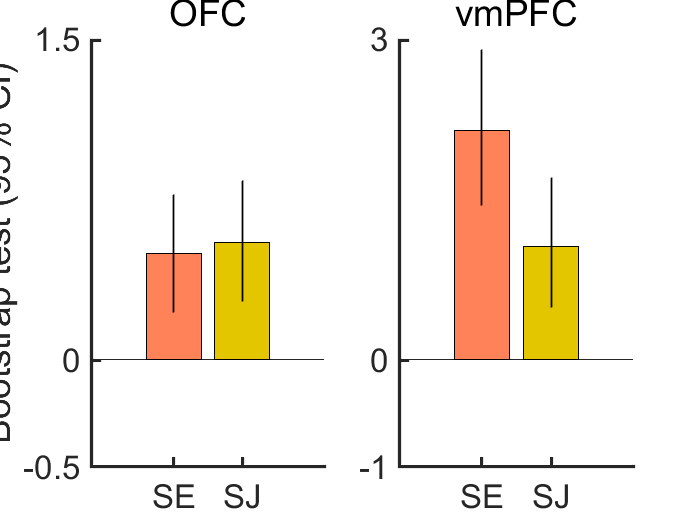

LMM = preprocssing the input table...
finding self-referentially activated electrodes for this analysis.
removing non-self-referentially activated electrodes
done!
  LMMSESJ with properties:

         coeff: []
        coeffl: []
        coeffh: []
    prediction: []
         index: [1×1 struct]
      preprocT: [180×19 table]
          data: [1265×15 table]
         model: "Tval ~ -1 + task:JPAnatomy + (1|subj) + (1|Density)"
           mdl: [1000×1 struct]


L_SEvsSJ = L_SEvsSJ.bars()

% write the report to file 
L_SEvsSJ.report('LMMSESJ')

writing the results to file:: results\LMMSESJ_bootResult.txt
done!


Now assessing if similar pattern can be found in the same brains. We identify individuals with electrodes in both OFC and vmPFC and assess how the predicted HFB value changes within same brain

L_SEvsSJ = L_SEvsSJ.predict; %  predict the effects using the fitted LMM model 
T = L_SEvsSJ.preprocT; % store the preprocessed table into T
T.Tval_pred = L_SEvsSJ.prediction.coeff % add LMM predition to the table
T.Tval_predL = L_SEvsSJ.prediction.coeffl % add LMM low boundary predition to the table 
T.Tval_predH = L_SEvsSJ.prediction.coeffl % add LMM high boundary predition to the table 
[SE ,SJ] = resultiEEG.find_sameBrain(T)

% ploting the result
col = stat.LMMSESJ.colors([1,3], 1); % get two colors with no reptitions
misc.plot_Fig1E(SE, SJ, col)

### **Self-coherence and Connotation modulate Rostral Prefrontal Cortex Self-Referential Processing **

Testing whether the self-coherece vs. sefl-incoherence modulate HFB in the OFC vs. vmPFC

% read data with a new define trial based on patients response (true and false)
data_SCoh = readtable('StimLock_TrFl.tsv', FileType='text'); % reading the tabular data
% create a new LMM object for self-coherence vs. self-incoherence
L_CohvsInCoh = stat.LMMTrFl(data_SCoh, 'Tval ~ -1 + task:JPAnatomy + (1|subj) + (1|Density)')   
% running bootstarping
L_CohvsInCoh = L_CohvsInCoh.bootstramp(L_CohvsInCoh.preprocT)

Plotting the result as a bar graph

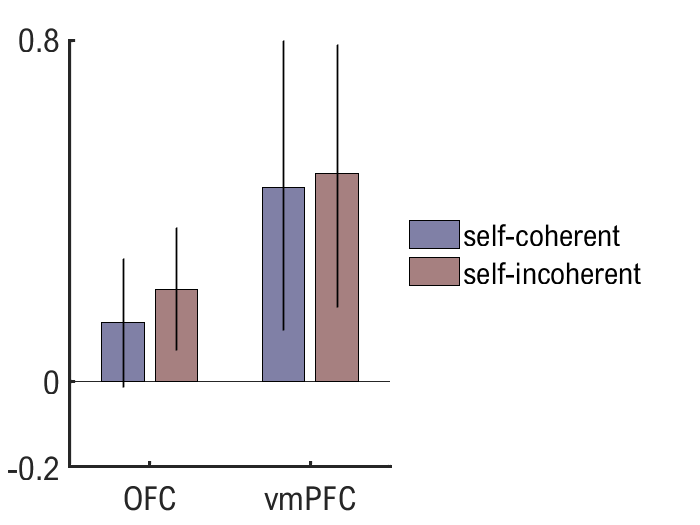

L_CohvsInCoh = L_CohvsInCoh.bars

% write the report to file 
L_CohvsInCoh.report('LMMSCohSInCoh')

We further assess if the valence of the stimuli and response alter the HBF in OFC and vmPFC  

% read data with a new define trial based on patients response (true and false)
data_PoNe = readtable('data\StimLock_PoNe.tsv', FileType='text'); % reading the tabular data
% create a new LMM object for poisitve vs. negative
L_PovsNe = stat.LMMPoNe(data_PoNe, 'Tval ~ -1 + task:JPAnatomy + (1|subj) + (1|Density)'); 

plot the t-values with violin plot

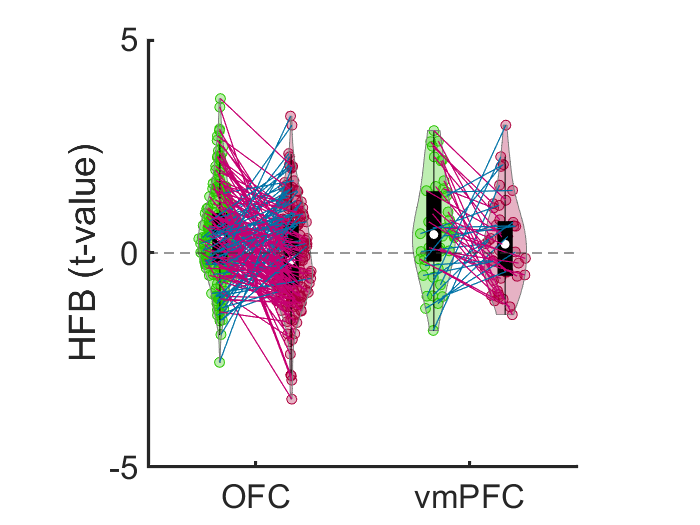

preprocssing the input table...
done!


ans = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: []
    preprocT: [488×16 table]
        data: [488×13 table]
       model: "Tval ~ -1 + task:JPAnatomy + (1|subj) + (1|Density)"
         mdl: []


figure
L_PovsNe.violin()

Now running the LMM model 

% running bootstarping
L_PovsNe =L_PovsNe.bootstramp(L_PovsNe.preprocT)

preprocssing the input table...
done!
Bootstrapping, please wait...
iteration : 1002
iteration : 1003
iteration : 1004
iteration : 1005
iteration : 1006
iteration : 1007
iteration : 1008
iteration : 1009
iteration : 1010
iteration : 1011
iteration : 1012
iteration : 1013
iteration : 1014
iteration : 1015
iteration : 1016
iteration : 1017
iteration : 1018
iteration : 1019
iteration : 1020
iteration : 1021
iteration : 1022
iteration : 1023
iteration : 1024
iteration : 1025
iteration : 1026
iteration : 1027
iteration : 1028
iteration : 1029
iteration : 1030
iteration : 1031
iteration : 1032
iteration : 1033
iteration : 1034
iteration : 1035
iteration : 1036
iteration : 1037
iteration : 1038
iteration : 1039
iteration : 1040
iteration : 1041
iteration : 1042
iteration : 1043
iteration : 1044
iteration : 1045
iteration : 1046
iteration : 1047
iteration : 1048
iteration : 1049
iteration : 1050
iteration : 1051
iteration : 1052
iteration : 1053
iteration : 1054
iteration : 1055
iteration : 10

L_PovsNe = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: []
    preprocT: [488×16 table]
        data: [488×13 table]
       model: "Tval ~ -1 + task:JPAnatomy + (1|subj) + (1|Density)"
         mdl: [1000×1 struct]


plot the LMM coefficients in a bar garph 

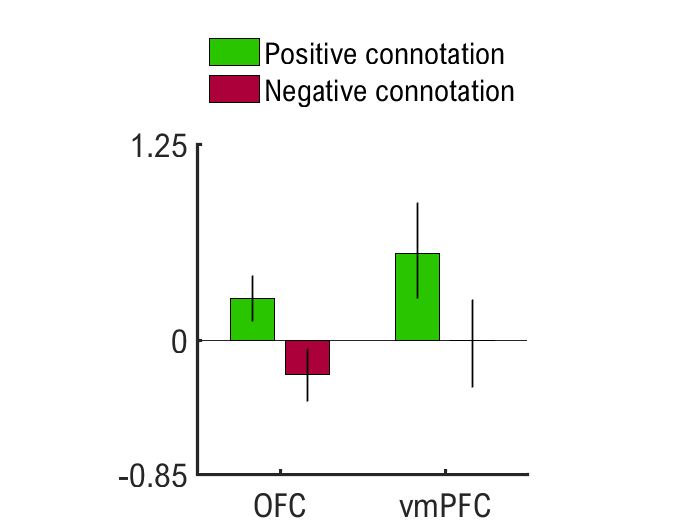

ans = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: [1×1 struct]
    preprocT: [488×16 table]
        data: [488×13 table]
       model: "Tval ~ -1 + task:JPAnatomy + (1|subj) + (1|Density)"
         mdl: [1000×1 struct]


L_PovsNe.bars() % bar plot the LMM coefficients 

Now we assess if there is association with BDI and the HFB in the OFC and vmPFC

% create a new LMM model with BDI predictor
% zscore BDI
data_PoNe.BDIz = (data_PoNe.BDI-nanmean(data_PoNe.BDI))./nanstd(data_PoNe.BDI);

Pysch = stat.LMMPoNe(data_PoNe, 'Tval ~ -1 + BDIz:task:JPAnatomy + (1|subj) + (1|Density)')  ;
% running bootstarping
Pysch = Pysch.bootstramp(Pysch.preprocT)

preprocssing the input table...
done!
Bootstrapping, please wait...
iteration : 2006
iteration : 2007
iteration : 2008
iteration : 2009
iteration : 2010
iteration : 2011
iteration : 2012
iteration : 2013
iteration : 2014
iteration : 2015
iteration : 2016
iteration : 2017
iteration : 2018
iteration : 2019
iteration : 2020
iteration : 2021
iteration : 2022
iteration : 2023
iteration : 2024
iteration : 2025
iteration : 2026
iteration : 2027
iteration : 2028
iteration : 2029
iteration : 2030
iteration : 2031
iteration : 2032
iteration : 2033
iteration : 2034
iteration : 2035
iteration : 2036
iteration : 2037
iteration : 2038
iteration : 2039
iteration : 2040
iteration : 2041
iteration : 2042
iteration : 2043
iteration : 2044
iteration : 2045
iteration : 2046
iteration : 2047
iteration : 2048
iteration : 2049
iteration : 2050
iteration : 2051
iteration : 2052
iteration : 2053
iteration : 2054
iteration : 2055
iteration : 2056
iteration : 2057
iteration : 2058
iteration : 2059
iteration : 20

Pysch = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: []
    preprocT: [488×17 table]
        data: [488×14 table]
       model: "Tval ~ -1 + BDIz:task:JPAnatomy + (1|subj) + (1|Density)"
         mdl: [1000×1 struct]


Plotting the LMM results for neuropsych data and neural HFB measure:

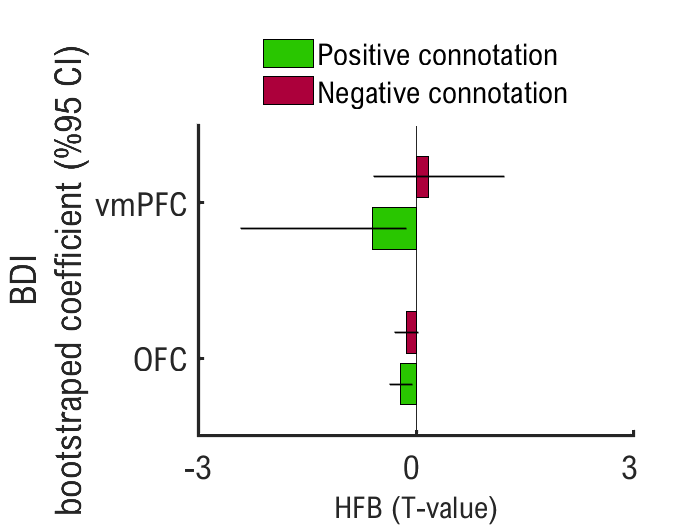

ans = preprocssing the input table...
done!
  LMMPoNe with properties:

       index: [1×1 struct]
    preprocT: [488×17 table]
        data: [488×14 table]
       model: "Tval ~ -1 + BDIz:task:JPAnatomy + (1|subj) + (1|Density)"
         mdl: [1000×1 struct]


Pysch.bars('on') % plot the coefficients, horizontal layout "on" 

We further assess the negative association between HFB in OFC and vmPFC and the psych (mood) data.

[POS, NEG, POSXNEG] = Pysch.subWPoNe(); % finds subjects with both pos and neg data

preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing the input table...
done!
preprocssing

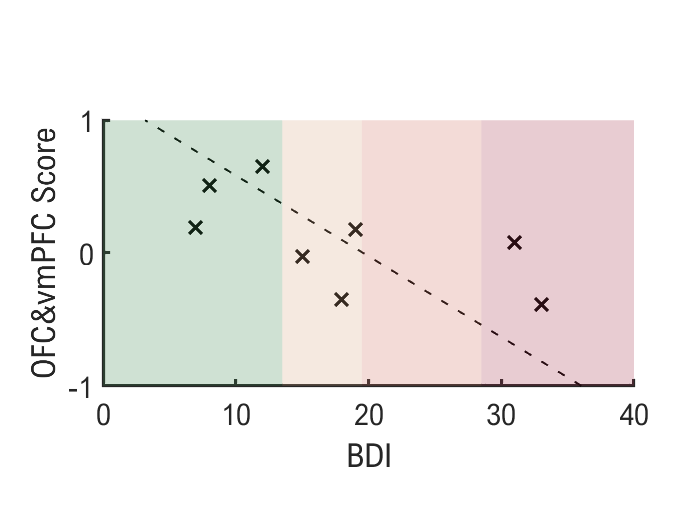

curve_score =      Linear model Poly1:
     curve_score(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -16.43  (-37.07, 4.211)
       p2 =        19.6  (12.17, 27.03)

goodness_score = struct with fields:
           sse: 404.8711
       rsquare: 0.3874
           dfe: 6
    adjrsquare: 0.2853
          rmse: 8.2145


output_score = struct with fields:
        numobs: 8
      numparam: 2
     residuals: [8×1 double]
      Jacobian: [8×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


[msr, BDI, b] = Pysch.OFCvmPFCMEASURE(POSXNEG); % save b for out-sample analysis
% plotting
[curve_score, goodness_score, output_score]  = Pysch.plot(msr, BDI)